clear

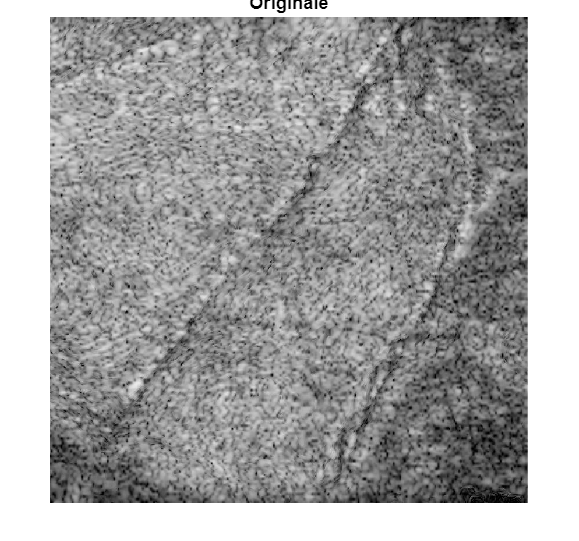

%LETTURA IMMAGINE
I = imread("imageGeneratedFrom3D\04-09-2023_Scavone_000\immagine_5_0.2772.jpg");
figure;imshow(I); title("Originale")

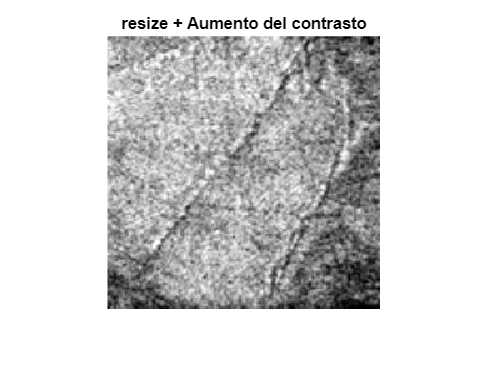


directions = [0 45 90 135];
dimDirectionalMatrix = 3;

% Caricamento dell'immagine di input
%A=imrotate(I,90);
%A=flip(A,2);

% Aumento del contrasto
A = imadjust(I);
% Ridimensioniamo l'immagine
Aresize=imresize(A, [128 128], 'bicubic'); 
clear A;
A=imresize(Aresize, 1.7 ,'bicubic'); % la dimensione diventa [x*1.7 y*1.7]
figure;imshow(A);title('resize + Aumento del contrasto');

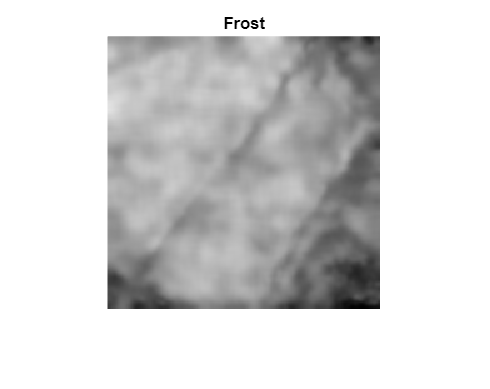

% Applicazione del filtro di Frost
Frost = fcnFrostFilter(A);
imshow(Frost);title('Frost');figure;

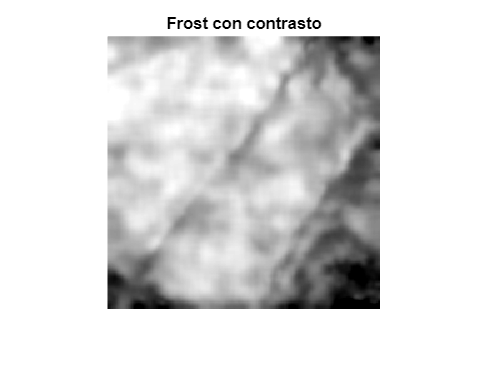



% Aumentiamo nuovamente il contrasto
adjusted = imadjust(Frost); % se il pixel è vicino a 0 lo porta ancora più vicino a 0. Lo stesso per l'1
imshow(adjusted);title('Frost con contrasto');figure;

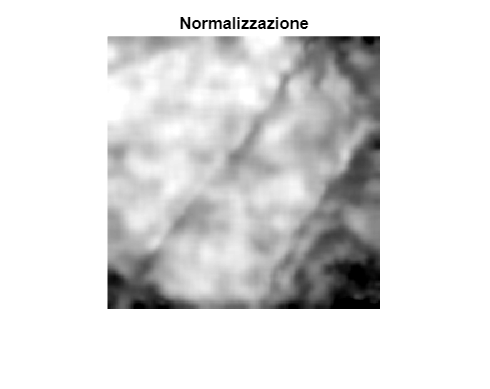

% Normalizzazione dell'immagine precedente
% I pixel dell'immagine sono divisi per il massimo valore assunto dai pixel
Anorm = mat2gray(adjusted); % mette tutti i valori tra 0 e 1
imshow(Anorm);title('Normalizzazione');figure;

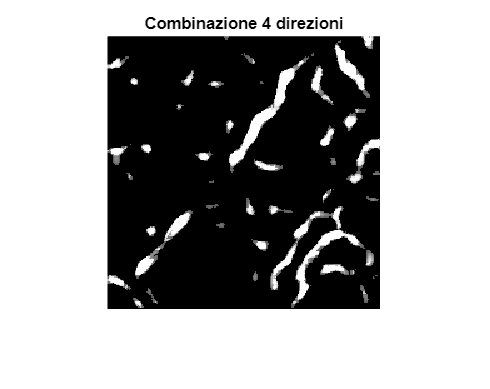


% Clonazione dell'immagine normalizzata in quattro copie
images(:,:,1) = Anorm; %Img0
images(:,:,2) = Anorm; %Img45
images(:,:,3) = Anorm; %Img90
images(:,:,4) = Anorm; %Img135

% Applicazione del filtro mediano solo per l'immagine che evidenzierà le linee 
% nella direzione di 0° (Img0)
%images(:,:,1) = medfilt2(images(:,:,1), [3 3]); %di default è 3x3 la finestra

% Filtraggio con operazione di convoluzione di ogni immagine per un elemento struttante
% generato con la funzione generaMatriceDirezionale
% Le immagini C1, C2, C3, C4 rappresentano le quattro immagini, ognuna delle quali è 
% deputata ad evidenziare le linee in una determinata direzione (C1 a 0°, C2 a 45°,
% C3 a 90° e C4 a 135°
dim = 10;
F = generaMatriceDirezionale(0, dim);
C1 = conv2(images(:,:,1), F, 'same');
% imshow(C1);title('C1');figure;
F = generaMatriceDirezionale(45, dim);
C2 = conv2(images(:,:,2), F, 'same');
% imshow(C2);title('C2');figure;
F = generaMatriceDirezionale(90, dim);
C3 = conv2(images(:,:,3), F, 'same');
% imshow(C3);title('C3');figure;
F = generaMatriceDirezionale(135, dim);
C4 = conv2(images(:,:,4), F, 'same');
% imshow(C4);title('C4');figure;

% Definizione dell'elemento strutturante di tipo disco
% utilizzato per l'operazione di bottom-hat
n=5;
SE = strel('disk',n,8); %definizione dell'elemento strutturante circolare
threshold = 0.35;
%nhood = getnhood(SE); 
%imagesc(nhood);

% Operazione di bottom-hat; dopo ogni operazione di bottom-hat eseguiamo subito 
% un'operazione di filtraggio e di ritaglio dei bordi per ripulire le immagini
IM1 = imbothat(C1, SE);
IM1(IM1<=threshold) = 0;
% imshow(IM1);title('imbothat IM1');figure;


% M = mean(mean(IM1));
% k = 3;
% threashold = k*M;
% IM1(IM1<=threashold) = 0;
% IM1 = IM1(n : end - n , n : end - n);
%  imshow(IM1);title('Binarizzazione IM1');figure;

IM2 = imbothat(C2, SE);
IM2(IM2<=threshold) = 0;

% imshow(IM2);title('imbothat IM2');figure;
% M = mean(mean(IM2));
% k = 3;
% threashold = k*M;
% IM2(IM2<=threashold) = 0;
% IM2 = IM2(n : end - n , n : end - n);
% imshow(IM2);title('Binarizzazione IM2');figure;


IM3 = imbothat(C3, SE);
IM3(IM3<=threshold) = 0;

% imshow(IM3);title('imbothat IM3');figure;

% M = mean(mean(IM3));
% k = 3;
% threashold = k*M;
% IM3(IM3<=threashold) = 0;
% IM3 = IM3(n : end - n , n : end - n);
% imshow(IM3);title('IM3');figure;

IM4 = imbothat(C4, SE);
IM4(IM4<=threshold) = 0;
% imshow(IM4);title('imbothat IM4');figure;

% M = mean(mean(IM4));
% k = 3;
% threashold = k*M;
% IM4(IM4<=threashold) = 0;
% IM4 = IM4(n : end - n , n : end - n);
% imshow(IM4);title('IM4');figure;

% Combinazione delle immagini ottenute al passo precedente
IMG = IM1+IM2+IM3+IM4;
imshow(IMG);title('Combinazione 4 direzioni');figure;

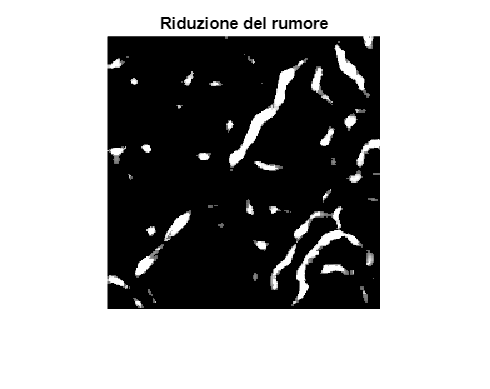

% Riduzione del rumore
M = mean(mean(IMG));
k = 3;
threashold = k*M;
IMG(IMG<=threashold) = 0;
imshow(IMG);title('Riduzione del rumore');figure;

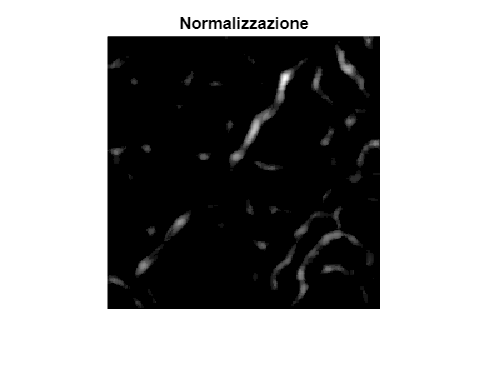

% Normalizzazione
IMGnorm = mat2gray(IMG);
imshow(IMGnorm);title('Normalizzazione');figure;

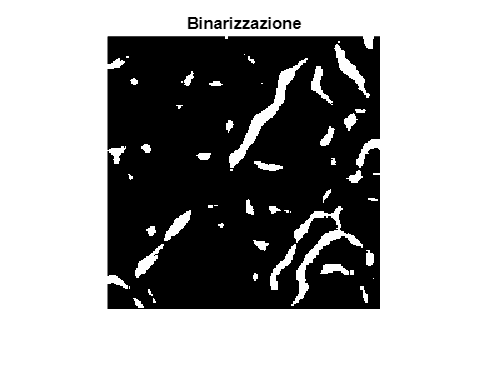

% Binarizzazione
Mprimo = mean(mean(IMGnorm));
IMGnorm(IMGnorm<=Mprimo) = 0;
IMGnorm(IMG>Mprimo) = 1;
imshow(IMGnorm);title('Binarizzazione');figure;

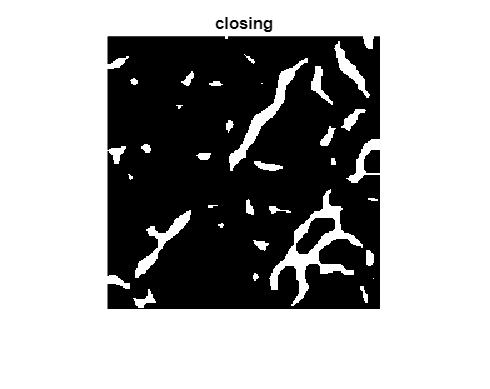


% Operazioni morfologiche
% closing
se=strel('disk', 6); 
imClosing=imclose(IMGnorm, se);
imshow(imClosing);title('closing');figure;

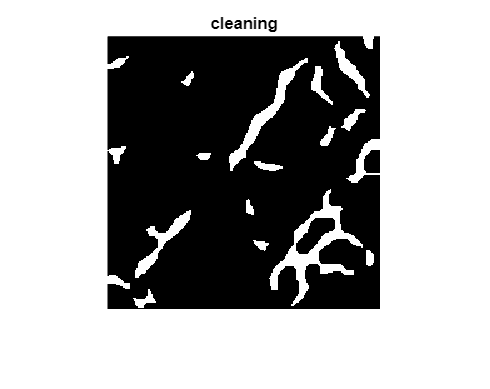

% trova, enumera le compomenti connesse
CC= bwconncomp(imClosing);
S = regionprops(CC, 'Area'); %calcola l'area di ogni componente connessa
%labelmatrix è più efficiente bwlabel e di bwlabeln perchè ritorna  
%la corrispondente label matrix nella classe numerica più piccola necessaria 
%per il numero di oggetti
L = labelmatrix(CC);   
%crea un'immagine binaria contenente solo le regioni connesse con area
%maggiore di 50
BW2 = ismember(L, find([S.Area] >= 50)); 
imshow(BW2);title('cleaning');figure;

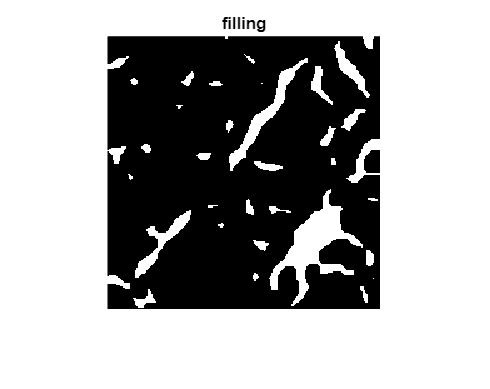


% chiusura buchi
ChiusuraBuchi= imfill(imClosing,'holes');
imshow(ChiusuraBuchi);title('filling');figure;

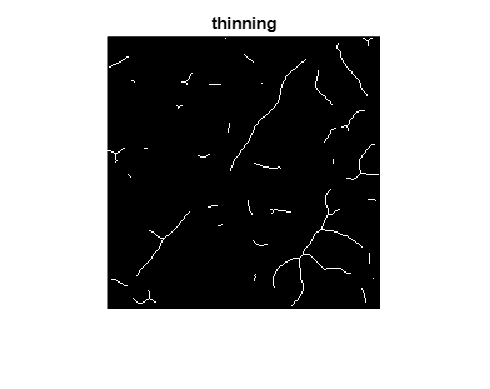


% thinning
Thinning= bwmorph(ChiusuraBuchi, 'thin', inf);
imshow(Thinning);title('thinning');figure;

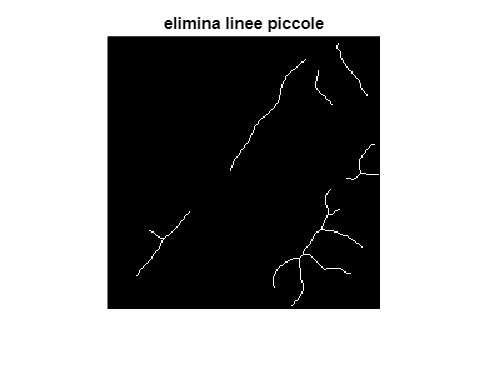


% elimina linee piu corte di...
BWz = bwareaopen(Thinning, 30); %rimuove le componenti connesse che contengono meno di 15 pixel
imshow(BWz);title('elimina linee piccole');figure;

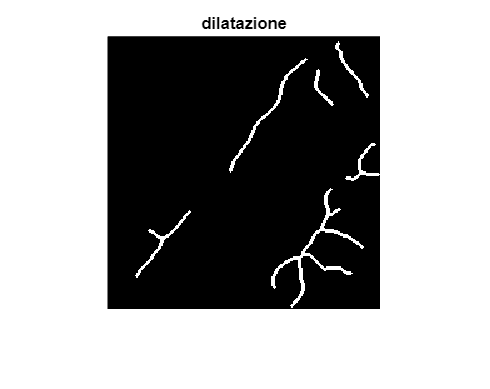


% Sovrapposizione del template con immagine di partenza
% templateUnint8 = im2uint8(BWz); %conversione dell'immagine in interi a 8-bit
% imshow(templateUnint8);title('template');figure;

% merge = A+templateUnint8;
% imshow(merge);title('merge');figure;


% %DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
dilatation_mask= strel('disk', 1);
dilatedImageDat= imdilate(BWz, dilatation_mask);
imshow(dilatedImageDat); title('dilatazione'); figure;

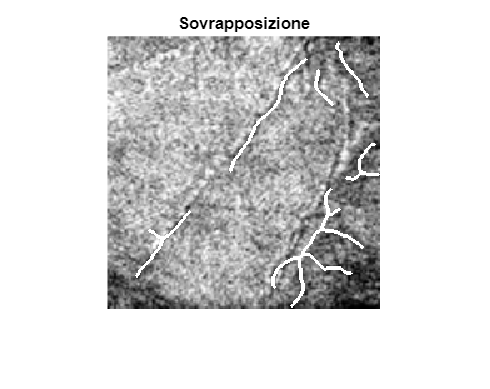

% merge = A+dilatedImageDat;

rgbImage = cat(3, A, A, A);
%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
[m n1]= size(A);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImageDat(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=255;
        rgbImage(i,j,3)=255;
        end 
    end 
 end	 


fig = figure();
imshow(rgbImage);title("Sovrapposizione")